%% MakeDLCTimeTable

% This script takes the results from DLCAppLite and produces a list of DLC events 

clear;
% This is the table updated from DLCAppLite:
OptoDLCTableName            =            dir('OptoDLCVideo_*Updated.csv');
OptoDLCTable                       =            readtable(fullfile(OptoDLCTableName.folder, OptoDLCTableName.name));

% This is the behavior table
% This is the table:
BpodMEDTableName          =             dir('BpodMEDTable_*.csv');
BpodMEDTable                    =              readtable(fullfile(BpodMEDTableName.folder, BpodMEDTableName.name));

TrialNums = [];
StimTypes = []; % 1. Opto Stim. 0. No stim
DLCTime   = []; % time of DLC trigger (in Bpod time) This is our guide to produce videoes

% loop through all the trials
% Find DLC trials that are no-stim

for i =1:length(OptoDLCTable.TrialNums)
       
    if OptoDLCTable.isGood(i)
        itrial_num      =       OptoDLCTable.TrialNums(i);
        TrialNums       =       [TrialNums; itrial_num];
        DLCTime         =       [DLCTime; BpodMEDTable.tDLC(BpodMEDTable.TrialsBpod == itrial_num)];
        StimTypes       =       [StimTypes; strcmp(OptoDLCTable.OptoStimTypes{i}, 'Stim_DLC')];
    end;
end;

DLCTable = table(TrialNums, StimTypes, DLCTime);

writetable(DLCTable, 'DLCTimeTable.csv')

%% Make ApproachTimeTable

% This script takes the results from DLCAppLite and produces a list of DLC events 

clear;
% This is the table updated from DLCAppLite:
OptoApproachTableName            =            dir('OptoApproachVideo_*.csv');
OptoApproachTable                =            readtable(fullfile(OptoApproachTableName.folder, OptoApproachTableName.name));

% This is the behavior table
% This is the table:
BpodMEDTableName                =             dir('BpodMEDTable_*.csv');
BpodMEDTable                    =              readtable(fullfile(BpodMEDTableName.folder, BpodMEDTableName.name));

TrialNums       = [];
StimTypes       = []; % 1. Opto Stim. 0. No stim
ApproachTime    = []; % time of DLC trigger (in Bpod time) This is our guide to produce videoes

% loop through all the trials
% Find DLC trials that are no-stim

for i =1:length(OptoApproachTable.TrialNums)

        itrial_num      =       OptoApproachTable.TrialNums(i);
        TrialNums       =       [TrialNums; itrial_num];
        ApproachTime    =       [ApproachTime; BpodMEDTable.tApproach(BpodMEDTable.TrialsBpod == itrial_num)];
        StimTypes       =       [StimTypes; strcmp(OptoApproachTable.OptoStimTypes{i}, 'Stim_Approach')];
 
end;

ApproachTable = table(TrialNums, StimTypes, ApproachTime);

writetable(ApproachTable, 'ApproachTimeTable.csv')


DLCTable = 118×3 table
    TrialNums    StimTypes    DLCTime
    _________    _________    _______

        4            0        64.185 
        5            1        68.841 
       10            0        130.56 
       11            0        149.74 
       12            0        163.74 
       15            0        198.94 
       17            0        225.18 
       18            0        238.16 
       20            0        265.58 
       21            0           278 
       24            1        322.44 
       25            0         334.7 
       28            0        364.98 
       29            0        377.24 
       30            0        389.02 
       34            0        432.46 


DLCTable = 118×3 table
    TrialNums    StimTypes    DLCTime
    _________    _________    _______

        4            0        64.185 
        5            1        68.841 
       10            0        130.56 
       11            0        149.74 
       12            0        163.74 
       15            0        198.94 
       17            0        225.18 
       18            0        238.16 
       20            0        265.58 
       21            0           278 
       24            1        322.44 
       25            0         334.7 
       28            0        364.98 
       29            0        377.24 
       30            0        389.02 
       34            0        432.46 


- Move seq video files to corresponding session folder e.g., Sessions\20220117 

- Move Wave data to corresponding session folder e.g., Sessions\20220117 

## Step 1: Get frame time and ROI amplitude

ans = 'Please select region of interests'

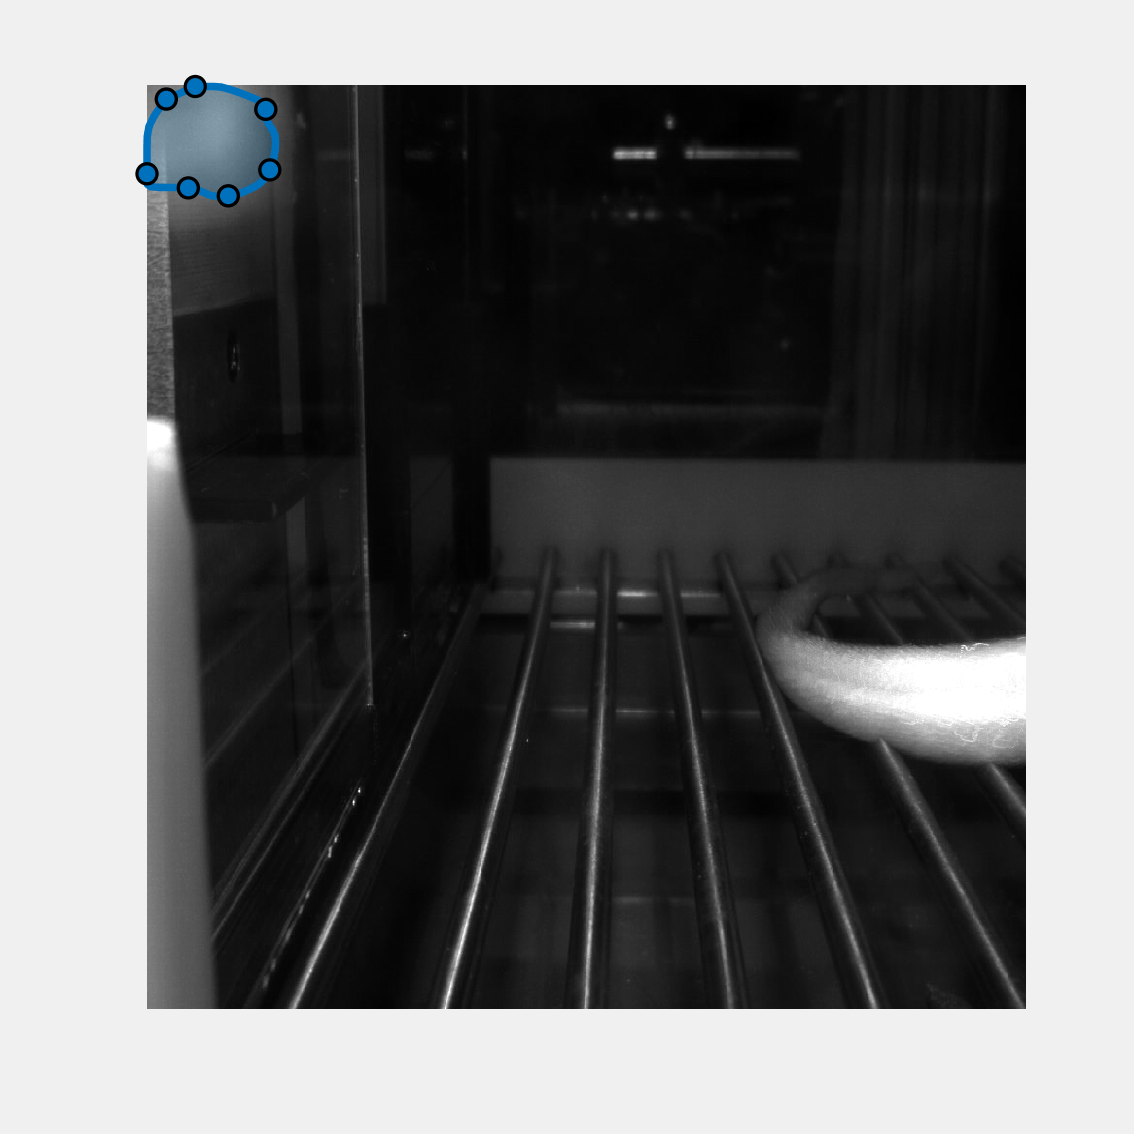

ans = 'Extracting ......'

ans = '100s frames extracted  1 '

ans = '100s frames extracted  2 '

ans = '100s frames extracted  3 '

ans = '100s frames extracted  4 '

ans = '100s frames extracted  5 '

ans = '100s frames extracted  6 '

ans = '100s frames extracted  7 '

ans = '100s frames extracted  8 '

ans = '100s frames extracted  9 '

ans = '100s frames extracted 10 '

ans = '100s frames extracted 11 '

ans = '100s frames extracted 12 '

ans = '100s frames extracted 13 '

ans = '100s frames extracted 14 '

ans = '100s frames extracted 15 '

ans = '100s frames extracted 16 '

ans = '100s frames extracted 17 '

ans = '100s frames extracted 18 '

ans = '100s frames extracted 19 '

ans = '100s frames extracted 20 '

ans = '100s frames extracted 21 '

ans = '100s frames extracted 22 '

ans = '100s frames extracted 23 '

ans = '100s frames extracted 24 '

ans = '100s frames extracted 25 '

ans = '100s frames extracted 26 '

ans = '100s frames extracted 27 '

ans = '100s frames extracted 28 '

ans = '100s frames extracted 29 '

ans = '100s frames extracted 30 '

ans = '100s frames extracted 31 '

ans = '100s frames extracted 32 '

ans = '100s frames extracted 33 '

ans = '100s frames extracted 34 '

ans = '100s frames extracted 35 '

ans = '100s frames extracted 36 '

ans = '100s frames extracted 37 '

ans = '100s frames extracted 38 '

ans = '100s frames extracted 39 '

ans = '100s frames extracted 40 '

ans = '100s frames extracted 41 '

ans = '100s frames extracted 42 '

ans = '100s frames extracted 43 '

ans = '100s frames extracted 44 '

ans = '100s frames extracted 45 '

ans = '100s frames extracted 46 '

ans = '100s frames extracted 47 '

ans = '100s frames extracted 48 '

ans = '100s frames extracted 49 '

ans = '100s frames extracted 50 '

ans = '100s frames extracted 51 '

ans = '100s frames extracted 52 '

ans = '100s frames extracted 53 '

ans = '100s frames extracted 54 '

ans = '100s frames extracted 55 '

ans = '100s frames extracted 56 '

ans = '100s frames extracted 57 '

ans = '100s frames extracted 58 '

ans = '100s frames extracted 59 '

ans = '100s frames extracted 60 '

ans = '100s frames extracted 61 '

ans = '100s frames extracted 62 '

ans = '100s frames extracted 63 '

ans = '100s frames extracted 64 '

ans = '100s frames extracted 65 '

ans = '100s frames extracted 66 '

ans = '100s frames extracted 67 '

ans = '100s frames extracted 68 '

ans = '100s frames extracted 69 '

ans = '100s frames extracted 70 '

ans = '100s frames extracted 71 '

ans = '100s frames extracted 72 '

ans = '100s frames extracted 73 '

ans = '100s frames extracted 74 '

ans = '100s frames extracted 75 '

ans = '100s frames extracted 76 '

ans = '100s frames extracted 77 '

ans = '100s frames extracted 78 '

ans = '100s frames extracted 79 '

ans = '100s frames extracted 80 '

ans = '100s frames extracted 81 '

ans = '100s frames extracted 82 '

ans = '100s frames extracted 83 '

ans = '100s frames extracted 84 '

ans = '100s frames extracted 85 '

ans = '100s frames extracted 86 '

ans = '100s frames extracted 87 '

ans = '100s frames extracted 88 '

ans = '100s frames extracted 89 '

ans = '100s frames extracted 90 '

ans = '100s frames extracted 91 '

ans = '100s frames extracted 92 '

ans = '100s frames extracted 93 '

ans = '100s frames extracted 94 '

ans = '100s frames extracted 95 '

ans = '100s frames extracted 96 '

ans = '100s frames extracted 97 '

ans = '100s frames extracted 98 '

ans = '100s frames extracted 99 '

ans = '100s frames extracted 100 '

ans = '100s frames extracted 101 '

ans = '100s frames extracted 102 '

ans = '100s frames extracted 103 '

ans = '100s frames extracted 104 '

ans = '100s frames extracted 105 '

ans = '100s frames extracted 106 '

ans = '100s frames extracted 107 '

ans = '100s frames extracted 108 '

ans = '100s frames extracted 109 '

ans = '100s frames extracted 110 '

ans = '100s frames extracted 111 '

ans = '100s frames extracted 112 '

ans = '100s frames extracted 113 '

ans = '100s frames extracted 114 '

ans = '100s frames extracted 115 '

ans = '100s frames extracted 116 '

ans = '100s frames extracted 117 '

ans = '100s frames extracted 118 '

ans = '100s frames extracted 119 '

ans = '100s frames extracted 120 '

ans = '100s frames extracted 121 '

ans = '100s frames extracted 122 '

ans = '100s frames extracted 123 '

ans = '100s frames extracted 124 '

ans = '100s frames extracted 125 '

ans = '100s frames extracted 126 '

ans = '100s frames extracted 127 '

ans = '100s frames extracted 128 '

ans = '100s frames extracted 129 '

ans = '100s frames extracted 130 '

ans = '100s frames extracted 131 '

ans = '100s frames extracted 132 '

ans = '100s frames extracted 133 '

ans = '100s frames extracted 134 '

ans = '100s frames extracted 135 '

ans = '100s frames extracted 136 '

ans = '100s frames extracted 137 '

ans = '100s frames extracted 138 '

ans = '100s frames extracted 139 '

ans = '100s frames extracted 140 '

ans = '100s frames extracted 141 '

ans = '100s frames extracted 142 '

ans = '100s frames extracted 143 '

ans = '100s frames extracted 144 '

ans = '100s frames extracted 145 '

ans = '100s frames extracted 146 '

ans = '100s frames extracted 147 '

ans = '100s frames extracted 148 '

ans = '100s frames extracted 149 '

ans = '100s frames extracted 150 '

ans = '100s frames extracted 151 '

ans = '100s frames extracted 152 '

ans = '100s frames extracted 153 '

ans = '100s frames extracted 154 '

ans = '100s frames extracted 155 '

ans = '100s frames extracted 156 '

ans = '100s frames extracted 157 '

ans = '100s frames extracted 158 '

ans = '100s frames extracted 159 '

ans = '100s frames extracted 160 '

ans = '100s frames extracted 161 '

ans = '100s frames extracted 162 '

ans = '100s frames extracted 163 '

ans = '100s frames extracted 164 '

ans = '100s frames extracted 165 '

ans = '100s frames extracted 166 '

ans = '100s frames extracted 167 '

ans = '100s frames extracted 168 '

ans = '100s frames extracted 169 '

ans = '100s frames extracted 170 '

ans = '100s frames extracted 171 '

ans = '100s frames extracted 172 '

ans = '100s frames extracted 173 '

ans = '100s frames extracted 174 '

ans = '100s frames extracted 175 '

ans = '100s frames extracted 176 '

ans = '100s frames extracted 177 '

ans = '100s frames extracted 178 '

ans = '100s frames extracted 179 '

ans = '100s frames extracted 180 '

ans = '100s frames extracted 181 '

ans = '100s frames extracted 182 '

ans = '100s frames extracted 183 '

ans = '100s frames extracted 184 '

ans = '100s frames extracted 185 '

ans = '100s frames extracted 186 '

ans = '100s frames extracted 187 '

ans = '100s frames extracted 188 '

ans = '100s frames extracted 189 '

ans = '100s frames extracted 190 '

ans = '100s frames extracted 191 '

ans = '100s frames extracted 192 '

ans = '100s frames extracted 193 '

ans = '100s frames extracted 194 '

ans = '100s frames extracted 195 '

ans = '100s frames extracted 196 '

ans = '100s frames extracted 197 '

ans = '100s frames extracted 198 '

ans = '100s frames extracted 199 '

ans = '100s frames extracted 200 '

ans = '100s frames extracted 201 '

ans = '100s frames extracted 202 '

ans = '100s frames extracted 203 '

ans = '100s frames extracted 204 '

ans = '100s frames extracted 205 '

ans = '100s frames extracted 206 '

ans = '100s frames extracted 207 '

ans = '100s frames extracted 208 '

ans = '100s frames extracted 209 '

ans = '100s frames extracted 210 '

ans = '100s frames extracted 211 '

ans = '100s frames extracted 212 '

ans = '100s frames extracted 213 '

ans = '100s frames extracted 214 '

ans = '100s frames extracted 215 '

ans = '100s frames extracted 216 '

ans = '100s frames extracted 217 '

ans = '100s frames extracted 218 '

ans = '100s frames extracted 219 '

ans = '100s frames extracted 220 '

ans = '100s frames extracted 221 '

ans = '100s frames extracted 222 '

ans = '100s frames extracted 223 '

ans = '100s frames extracted 224 '

ans = '100s frames extracted 225 '

ans = '100s frames extracted 226 '

ans = '100s frames extracted 227 '

ans = '100s frames extracted 228 '

ans = '100s frames extracted 229 '

ans = '100s frames extracted 230 '

ans = '100s frames extracted 231 '

ans = '100s frames extracted 232 '

ans = '100s frames extracted 233 '

ans = '100s frames extracted 234 '

ans = '100s frames extracted 235 '

ans = '100s frames extracted 236 '

ans = '100s frames extracted 237 '

ans = '100s frames extracted 238 '

ans = '100s frames extracted 239 '

ans = '100s frames extracted 240 '

ans = '100s frames extracted 241 '

ans = '100s frames extracted 242 '

ans = '100s frames extracted 243 '

ans = '100s frames extracted 244 '

ans = '100s frames extracted 245 '

ans = '100s frames extracted 246 '

ans = '100s frames extracted 247 '

ans = '100s frames extracted 248 '

ans = '100s frames extracted 249 '

ans = '100s frames extracted 250 '

ans = '100s frames extracted 251 '

ans = '100s frames extracted 252 '

ans = '100s frames extracted 253 '

ans = '100s frames extracted 254 '

ans = '100s frames extracted 255 '

ans = '100s frames extracted 256 '

ans = '100s frames extracted 257 '

ans = '100s frames extracted 258 '

ans = '100s frames extracted 259 '

ans = '100s frames extracted 260 '

ans = '100s frames extracted 261 '

ans = '100s frames extracted 262 '

ans = '100s frames extracted 263 '

ans = '100s frames extracted 264 '

ans = '100s frames extracted 265 '

ans = '100s frames extracted 266 '

ans = '100s frames extracted 267 '

ans = '100s frames extracted 268 '

ans = '100s frames extracted 269 '

ans = '100s frames extracted 270 '

ans = '100s frames extracted 271 '

ans = '100s frames extracted 272 '

ans = '100s frames extracted 273 '

ans = '100s frames extracted 274 '

ans = '100s frames extracted 275 '

ans = '100s frames extracted 276 '

ans = '100s frames extracted 277 '

ans = '100s frames extracted 278 '

ans = '100s frames extracted 279 '

ans = '100s frames extracted 280 '

ans = '100s frames extracted 281 '

ans = '100s frames extracted 282 '

ans = '100s frames extracted 283 '

ans = '100s frames extracted 284 '

ans = '100s frames extracted 285 '

ans = '100s frames extracted 286 '

ans = '100s frames extracted 287 '

ans = '100s frames extracted 288 '

ans = '100s frames extracted 289 '

ans = '100s frames extracted 290 '

ans = '100s frames extracted 291 '

ans = '100s frames extracted 292 '

ans = '100s frames extracted 293 '

ans = '100s frames extracted 294 '

ans = '100s frames extracted 295 '

ans = '100s frames extracted 296 '

ans = '100s frames extracted 297 '

ans = '100s frames extracted 298 '

ans = '100s frames extracted 299 '

ans = '100s frames extracted 300 '

ans = '100s frames extracted 301 '

ans = '100s frames extracted 302 '

ans = '100s frames extracted 303 '

ans = '100s frames extracted 304 '

ans = '100s frames extracted 305 '

ans = '100s frames extracted 306 '

ans = '100s frames extracted 307 '

ans = '100s frames extracted 308 '

ans = '100s frames extracted 309 '

ans = '100s frames extracted 310 '

ans = '100s frames extracted 311 '

ans = '100s frames extracted 312 '

ans = '100s frames extracted 313 '

ans = '100s frames extracted 314 '

ans = '100s frames extracted 315 '

ans = '100s frames extracted 316 '

ans = '100s frames extracted 317 '

ans = '100s frames extracted 318 '

ans = '100s frames extracted 319 '

ans = '100s frames extracted 320 '

ans = '100s frames extracted 321 '

ans = '100s frames extracted 322 '

ans = '100s frames extracted 323 '

ans = '100s frames extracted 324 '

ans = '100s frames extracted 325 '

ans = '100s frames extracted 326 '

ans = '100s frames extracted 327 '

ans = '100s frames extracted 328 '

ans = '100s frames extracted 329 '

ans = '100s frames extracted 330 '

ans = '100s frames extracted 331 '

ans = '100s frames extracted 332 '

ans = '100s frames extracted 333 '

ans = '100s frames extracted 334 '

ans = '100s frames extracted 335 '

ans = '100s frames extracted 336 '

ans = '100s frames extracted 337 '

ans = '100s frames extracted 338 '

ans = '100s frames extracted 339 '

ans = '100s frames extracted 340 '

ans = '100s frames extracted 341 '

ans = '100s frames extracted 342 '

ans = '100s frames extracted 343 '

ans = '100s frames extracted 344 '

ans = '100s frames extracted 345 '

ans = '100s frames extracted 346 '

ans = '100s frames extracted 347 '

ans = '100s frames extracted 348 '

ans = '100s frames extracted 349 '

ans = '100s frames extracted 350 '

ans = '100s frames extracted 351 '

ans = '100s frames extracted 352 '

ans = '100s frames extracted 353 '

ans = '100s frames extracted 354 '

ans = '100s frames extracted 355 '

ans = '100s frames extracted 356 '

ans = '100s frames extracted 357 '

ans = '100s frames extracted 358 '

ans = '100s frames extracted 359 '

ans = '100s frames extracted 360 '

ans = '100s frames extracted 361 '

ans = '100s frames extracted 362 '

ans = '100s frames extracted 363 '

ans = '100s frames extracted 364 '

ans = '100s frames extracted 365 '

ans = '100s frames extracted 366 '

ans = '100s frames extracted 367 '

ans = '100s frames extracted 368 '

ans = '100s frames extracted 369 '

ans = '100s frames extracted 370 '

ans = '100s frames extracted 371 '

ans = '100s frames extracted 372 '

ans = '100s frames extracted 373 '

ans = '100s frames extracted 374 '

ans = '100s frames extracted 375 '

ans = '100s frames extracted 376 '

ans = '100s frames extracted 377 '

ans = '100s frames extracted 378 '

ans = '100s frames extracted 379 '

ans = '100s frames extracted 380 '

ans = '100s frames extracted 381 '

ans = '100s frames extracted 382 '

ans = '100s frames extracted 383 '

ans = '100s frames extracted 384 '

ans = '100s frames extracted 385 '

ans = '100s frames extracted 386 '

ans = '100s frames extracted 387 '

ans = '100s frames extracted 388 '

ans = '100s frames extracted 389 '

ans = '100s frames extracted 390 '

ans = '100s frames extracted 391 '

ans = '100s frames extracted 392 '

ans = '100s frames extracted 393 '

ans = '100s frames extracted 394 '

ans = '100s frames extracted 395 '

ans = '100s frames extracted 396 '

ans = '100s frames extracted 397 '

ans = '100s frames extracted 398 '

ans = '100s frames extracted 399 '

ans = '100s frames extracted 400 '

ans = '100s frames extracted 401 '

ans = '100s frames extracted 402 '

ans = '100s frames extracted 403 '

ans = '100s frames extracted 404 '

ans = '100s frames extracted 405 '

ans = '100s frames extracted 406 '

ans = '100s frames extracted 407 '

ans = '100s frames extracted 408 '

ans = '100s frames extracted 409 '

ans = '100s frames extracted 410 '

ans = '100s frames extracted 411 '

ans = '100s frames extracted 412 '

ans = '100s frames extracted 413 '

ans = '100s frames extracted 414 '

ans = '100s frames extracted 415 '

ans = '100s frames extracted 416 '

ans = '100s frames extracted 417 '

ans = '100s frames extracted 418 '

ans = '100s frames extracted 419 '

ans = '100s frames extracted 420 '

ans = '100s frames extracted 421 '

ans = '100s frames extracted 422 '

ans = '100s frames extracted 423 '

ans = '100s frames extracted 424 '

ans = '100s frames extracted 425 '

ans = '100s frames extracted 426 '

ans = '100s frames extracted 427 '

ans = '100s frames extracted 428 '

ans = '100s frames extracted 429 '

ans = '100s frames extracted 430 '

ans = '100s frames extracted 431 '

ans = '100s frames extracted 432 '

ans = '100s frames extracted 433 '

ans = '100s frames extracted 434 '

ans = '100s frames extracted 435 '

ans = '100s frames extracted 436 '

ans = '100s frames extracted 437 '

ans = '100s frames extracted 438 '

ans = '100s frames extracted 439 '

ans = '100s frames extracted 440 '

ans = '100s frames extracted 441 '

ans = '100s frames extracted 442 '

ans = '100s frames extracted 443 '

ans = '100s frames extracted 444 '

ans = '100s frames extracted 445 '

ans = '100s frames extracted 446 '

ans = '100s frames extracted 447 '

ans = '100s frames extracted 448 '

ans = '100s frames extracted 449 '

ans = '100s frames extracted 450 '

ans = '100s frames extracted 451 '

ans = '100s frames extracted 452 '

ans = '100s frames extracted 453 '

ans = '100s frames extracted 454 '

ans = '100s frames extracted 455 '

ans = '100s frames extracted 456 '

ans = '100s frames extracted 457 '

ans = '100s frames extracted 458 '

ans = '100s frames extracted 459 '

ans = '100s frames extracted 460 '

ans = '100s frames extracted 461 '

ans = '100s frames extracted 462 '

ans = '100s frames extracted 463 '

ans = '100s frames extracted 464 '

ans = '100s frames extracted 465 '

ans = '100s frames extracted 466 '

ans = '100s frames extracted 467 '

ans = '100s frames extracted 468 '

ans = '100s frames extracted 469 '

ans = '100s frames extracted 470 '

ans = '100s frames extracted 471 '

ans = '100s frames extracted 472 '

ans = '100s frames extracted 473 '

ans = '100s frames extracted 474 '

ans = '100s frames extracted 475 '

ans = '100s frames extracted 476 '

ans = '100s frames extracted 477 '

ans = '100s frames extracted 478 '

ans = '100s frames extracted 479 '

ans = '100s frames extracted 480 '

ans = '100s frames extracted 481 '

ans = '100s frames extracted 482 '

ans = '100s frames extracted 483 '

ans = '100s frames extracted 484 '

ans = '100s frames extracted 485 '

ans = '100s frames extracted 486 '

ans = '100s frames extracted 487 '

ans = '100s frames extracted 488 '

ans = '100s frames extracted 489 '

ans = '100s frames extracted 490 '

ans = '100s frames extracted 491 '

ans = '100s frames extracted 492 '

ans = '100s frames extracted 493 '

ans = '100s frames extracted 494 '

ans = '100s frames extracted 495 '

ans = '100s frames extracted 496 '

ans = '100s frames extracted 497 '

ans = '100s frames extracted 498 '

ans = '100s frames extracted 499 '

ans = '100s frames extracted 500 '

ans = '100s frames extracted 501 '

ans = '100s frames extracted 502 '

ans = '100s frames extracted 503 '

ans = '100s frames extracted 504 '

ans = '100s frames extracted 505 '

ans = '100s frames extracted 506 '

ans = '100s frames extracted 507 '

ans = '100s frames extracted 508 '

ans = '100s frames extracted 509 '

ans = '100s frames extracted 510 '

ans = '100s frames extracted 511 '

ans = '100s frames extracted 512 '

ans = '100s frames extracted 513 '

ans = '100s frames extracted 514 '

ans = '100s frames extracted 515 '

ans = '100s frames extracted 516 '

ans = '100s frames extracted 517 '

ans = '100s frames extracted 518 '

ans = '100s frames extracted 519 '

ans = '100s frames extracted 520 '

ans = '100s frames extracted 521 '

ans = '100s frames extracted 522 '

ans = '100s frames extracted 523 '

ans = '100s frames extracted 524 '

ans = '100s frames extracted 525 '

ans = '100s frames extracted 526 '

ans = '100s frames extracted 527 '

ans = '100s frames extracted 528 '

ans = '100s frames extracted 529 '

ans = '100s frames extracted 530 '

ans = '100s frames extracted 531 '

ans = '100s frames extracted 532 '

ans = '100s frames extracted 533 '

ans = '100s frames extracted 534 '

ans = '100s frames extracted 535 '

ans = '100s frames extracted 536 '

ans = '100s frames extracted 537 '

ans = '100s frames extracted 538 '

ans = '100s frames extracted 539 '

ans = '100s frames extracted 540 '

ans = '100s frames extracted 541 '

ans = '100s frames extracted 542 '

ans = '100s frames extracted 543 '

ans = '100s frames extracted 544 '

ans = '100s frames extracted 545 '

ans = '100s frames extracted 546 '

ans = '100s frames extracted 547 '

ans = '100s frames extracted 548 '

ans = '100s frames extracted 549 '

ans = '100s frames extracted 550 '

ans = '100s frames extracted 551 '

ans = '100s frames extracted 552 '

ans = '100s frames extracted 553 '

ans = '100s frames extracted 554 '

ans = '100s frames extracted 555 '

ans = '100s frames extracted 556 '

ans = '100s frames extracted 557 '

ans = '100s frames extracted 558 '

ans = '100s frames extracted 559 '

ans = '100s frames extracted 560 '

ans = '100s frames extracted 561 '

ans = '100s frames extracted 562 '

ans = '100s frames extracted 563 '

ans = '100s frames extracted 564 '

ans = '100s frames extracted 565 '

ans = '100s frames extracted 566 '

ans = '100s frames extracted 567 '

ans = '100s frames extracted 568 '

ans = '100s frames extracted 569 '

ans = '100s frames extracted 570 '

ans = '100s frames extracted 571 '

ans = '100s frames extracted 572 '

ans = '100s frames extracted 573 '

ans = '100s frames extracted 574 '

ans = '100s frames extracted 575 '

ans = '100s frames extracted 576 '

ans = '100s frames extracted 577 '

ans = '100s frames extracted 578 '

ans = '100s frames extracted 579 '

ans = '100s frames extracted 580 '

ans = '100s frames extracted 581 '

ans = '100s frames extracted 582 '

ans = '100s frames extracted 583 '

ans = '100s frames extracted 584 '

ans = '100s frames extracted 585 '

ans = '100s frames extracted 586 '

ans = '100s frames extracted 587 '

ans = '100s frames extracted 588 '

ans = '100s frames extracted 589 '

ans = '100s frames extracted 590 '

ans = '100s frames extracted 591 '

ans = '100s frames extracted 592 '

ans = '100s frames extracted 593 '

ans = '100s frames extracted 594 '

ans = '100s frames extracted 595 '

ans = '100s frames extracted 596 '

ans = '100s frames extracted 597 '

ans = '100s frames extracted 598 '

ans = '100s frames extracted 599 '

ans = '100s frames extracted 600 '

ans = '100s frames extracted 601 '

ans = '100s frames extracted 602 '

ans = '100s frames extracted 603 '

ans = '100s frames extracted 604 '

ans = '100s frames extracted 605 '

ans = '100s frames extracted 606 '

ans = '100s frames extracted 607 '

ans = '100s frames extracted 608 '

ans = '100s frames extracted 609 '

ans = '100s frames extracted 610 '

ans = '100s frames extracted 611 '

ans = '100s frames extracted 612 '

ans = '100s frames extracted 613 '

ans = '100s frames extracted 614 '

ans = '100s frames extracted 615 '

ans = '100s frames extracted 616 '

ans = '100s frames extracted 617 '

ans = '100s frames extracted 618 '

ans = '100s frames extracted 619 '

ans = '100s frames extracted 620 '

ans = '100s frames extracted 621 '

ans = '100s frames extracted 622 '

ans = '100s frames extracted 623 '

ans = '100s frames extracted 624 '

ans = '100s frames extracted 625 '

ans = '100s frames extracted 626 '

ans = '100s frames extracted 627 '

ans = '100s frames extracted 628 '

ans = '100s frames extracted 629 '

ans = '100s frames extracted 630 '

ans = '100s frames extracted 631 '

ans = '100s frames extracted 632 '

ans = '100s frames extracted 633 '

ans = '100s frames extracted 634 '

ans = '100s frames extracted 635 '

ans = '100s frames extracted 636 '

ans = '100s frames extracted 637 '

ans = '100s frames extracted 638 '

ans = '100s frames extracted 639 '

ans = '100s frames extracted 640 '

ans = '100s frames extracted 641 '

ans = '100s frames extracted 642 '

ans = '100s frames extracted 643 '

ans = '100s frames extracted 644 '

ans = '100s frames extracted 645 '

ans = '100s frames extracted 646 '

ans = '100s frames extracted 647 '

ans = '100s frames extracted 648 '

ans = '100s frames extracted 649 '

ans = '100s frames extracted 650 '

ans = '100s frames extracted 651 '

ans = '100s frames extracted 652 '

ans = '100s frames extracted 653 '

ans = '100s frames extracted 654 '

ans = '100s frames extracted 655 '

ans = '100s frames extracted 656 '

ans = '100s frames extracted 657 '

ans = '100s frames extracted 658 '

ans = '100s frames extracted 659 '

ans = '100s frames extracted 660 '

ans = '100s frames extracted 661 '

ans = '100s frames extracted 662 '

ans = '100s frames extracted 663 '

ans = '100s frames extracted 664 '

ans = '100s frames extracted 665 '

ans = '100s frames extracted 666 '

ans = '100s frames extracted 667 '

ans = '100s frames extracted 668 '

ans = '100s frames extracted 669 '

ans = '100s frames extracted 670 '

ans = '100s frames extracted 671 '

ans = '100s frames extracted 672 '

ans = '100s frames extracted 673 '

ans = '100s frames extracted 674 '

ans = '100s frames extracted 675 '

ans = '100s frames extracted 676 '

ans = '100s frames extracted 677 '

ans = '100s frames extracted 678 '

ans = '100s frames extracted 679 '

ans = '100s frames extracted 680 '

ans = '100s frames extracted 681 '

ans = '100s frames extracted 682 '

ans = '100s frames extracted 683 '

ans = '100s frames extracted 684 '

ans = '100s frames extracted 685 '

ans = '100s frames extracted 686 '

ans = '100s frames extracted 687 '

ans = '100s frames extracted 688 '

ans = '100s frames extracted 689 '

ans = '100s frames extracted 690 '

ans = '100s frames extracted 691 '

ans = '100s frames extracted 692 '

ans = '100s frames extracted 693 '

ans = '100s frames extracted 694 '

ans = '100s frames extracted 695 '

ans = '100s frames extracted 696 '

ans = '100s frames extracted 697 '

ans = '100s frames extracted 698 '

ans = '100s frames extracted 699 '

ans = '100s frames extracted 700 '

ans = '100s frames extracted 701 '

ans = '100s frames extracted 702 '

ans = '100s frames extracted 703 '

ans = '100s frames extracted 704 '

ans = '100s frames extracted 705 '

ans = '100s frames extracted 706 '

ans = '100s frames extracted 707 '

ans = '100s frames extracted 708 '

ans = '100s frames extracted 709 '

ans = '100s frames extracted 710 '

ans = '100s frames extracted 711 '

ans = '100s frames extracted 712 '

ans = '100s frames extracted 713 '

ans = '100s frames extracted 714 '

ans = '100s frames extracted 715 '

ans = '100s frames extracted 716 '

ans = '100s frames extracted 717 '

ans = '100s frames extracted 718 '

ans = '100s frames extracted 719 '

ans = '100s frames extracted 720 '

ans = '100s frames extracted 721 '

ans = '100s frames extracted 722 '

ans = '100s frames extracted 723 '

ans = '100s frames extracted 724 '

ans = '100s frames extracted 725 '

ans = '100s frames extracted 726 '

ans = '100s frames extracted 727 '

ans = '100s frames extracted 728 '

ans = '100s frames extracted 729 '

ans = '100s frames extracted 730 '

ans = '100s frames extracted 731 '

ans = '100s frames extracted 732 '

ans = '100s frames extracted 733 '

ans = '100s frames extracted 734 '

ans = '100s frames extracted 735 '

ans = '100s frames extracted 736 '

ans = '100s frames extracted 737 '

ans = '100s frames extracted 738 '

ans = '100s frames extracted 739 '

ans = '100s frames extracted 740 '

ans = '100s frames extracted 741 '

ans = '100s frames extracted 742 '

ans = '100s frames extracted 743 '

ans = '100s frames extracted 744 '

ans = '100s frames extracted 745 '

ans = '100s frames extracted 746 '

ans = '100s frames extracted 747 '

ans = '100s frames extracted 748 '

ans = '100s frames extracted 749 '

ans = '100s frames extracted 750 '

ans = '100s frames extracted 751 '

ans = '100s frames extracted 752 '

ans = '100s frames extracted 753 '

ans = '100s frames extracted 754 '

ans = '100s frames extracted 755 '

ans = '100s frames extracted 756 '

ans = '100s frames extracted 757 '

ans = '100s frames extracted 758 '

ans = '100s frames extracted 759 '

ans = '100s frames extracted 760 '

ans = '100s frames extracted 761 '

ans = '100s frames extracted 762 '

ans = '100s frames extracted 763 '

ans = '100s frames extracted 764 '

ans = '100s frames extracted 765 '

ans = '100s frames extracted 766 '

ans = '100s frames extracted 767 '

ans = '100s frames extracted 768 '

ans = '100s frames extracted 769 '

ans = '100s frames extracted 770 '

ans = '100s frames extracted 771 '

ans = '100s frames extracted 772 '

ans = '100s frames extracted 773 '

ans = '100s frames extracted 774 '

ans = '100s frames extracted 775 '

ans = '100s frames extracted 776 '

ans = '100s frames extracted 777 '

ans = '100s frames extracted 778 '

ans = '100s frames extracted 779 '

ans = '100s frames extracted 780 '

ans = '100s frames extracted 781 '

ans = '100s frames extracted 782 '

ans = '100s frames extracted 783 '

ans = '100s frames extracted 784 '

ans = '100s frames extracted 785 '

ans = '100s frames extracted 786 '

ans = '100s frames extracted 787 '

ans = '100s frames extracted 788 '

ans = '100s frames extracted 789 '

ans = '100s frames extracted 790 '

ans = '100s frames extracted 791 '

ans = '100s frames extracted 792 '

ans = '100s frames extracted 793 '

ans = '100s frames extracted 794 '

ans = '100s frames extracted 795 '

ans = '100s frames extracted 796 '

ans = '100s frames extracted 797 '

ans = '100s frames extracted 798 '

ans = '100s frames extracted 799 '

ans = '100s frames extracted 800 '

ans = '100s frames extracted 801 '

ans = '100s frames extracted 802 '

ans = '100s frames extracted 803 '

ans = '100s frames extracted 804 '

ans = '100s frames extracted 805 '

ans = '100s frames extracted 806 '

ans = '100s frames extracted 807 '

ans = '100s frames extracted 808 '

ans = '100s frames extracted 809 '

ans = '100s frames extracted 810 '

ans = '100s frames extracted 811 '

ans = '100s frames extracted 812 '

ans = '100s frames extracted 813 '

ans = '100s frames extracted 814 '

ans = '100s frames extracted 815 '

ans = '100s frames extracted 816 '

ans = '100s frames extracted 817 '

ans = '100s frames extracted 818 '

ans = '100s frames extracted 819 '

ans = '100s frames extracted 820 '

ans = '100s frames extracted 821 '

ans = '100s frames extracted 822 '

ans = '100s frames extracted 823 '

ans = '100s frames extracted 824 '

ans = '100s frames extracted 825 '

ans = '100s frames extracted 826 '

ans = '100s frames extracted 827 '

ans = '100s frames extracted 828 '

ans = '100s frames extracted 829 '

ans = '100s frames extracted 830 '

ans = '100s frames extracted 831 '

ans = '100s frames extracted 832 '

ans = '100s frames extracted 833 '

ans = '100s frames extracted 834 '

ans = '100s frames extracted 835 '

ans = '100s frames extracted 836 '

ans = '100s frames extracted 837 '

ans = '100s frames extracted 838 '

ans = '100s frames extracted 839 '

ans = '100s frames extracted 840 '

ans = '100s frames extracted 841 '

ans = '100s frames extracted 842 '

ans = '100s frames extracted 843 '

ans = '100s frames extracted 844 '

ans = '100s frames extracted 845 '

ans = '100s frames extracted 846 '

ans = '100s frames extracted 847 '

ans = '100s frames extracted 848 '

ans = '100s frames extracted 849 '

ans = '100s frames extracted 850 '

ans = '100s frames extracted 851 '

ans = '100s frames extracted 852 '

ans = '100s frames extracted 853 '

ans = '100s frames extracted 854 '

ans = '100s frames extracted 855 '

ans = '100s frames extracted 856 '

ans = '100s frames extracted 857 '

ans = '100s frames extracted 858 '

ans = '100s frames extracted 859 '

ans = '100s frames extracted 860 '

ans = '100s frames extracted 861 '

ans = '100s frames extracted 862 '

ans = '100s frames extracted 863 '

ans = '100s frames extracted 864 '

ans = '100s frames extracted 865 '

ans = '100s frames extracted 866 '

ans = '100s frames extracted 867 '

ans = '100s frames extracted 868 '

ans = '100s frames extracted 869 '

ans = '100s frames extracted 870 '

ans = '100s frames extracted 871 '

ans = '100s frames extracted 872 '

ans = '100s frames extracted 873 '

ans = '100s frames extracted 874 '

ans = '100s frames extracted 875 '

ans = '100s frames extracted 876 '

ans = '100s frames extracted 877 '

ans = '100s frames extracted 878 '

ans = '100s frames extracted 879 '

ans = '100s frames extracted 880 '

ans = '100s frames extracted 881 '

ans = '100s frames extracted 882 '

ans = '100s frames extracted 883 '

ans = '100s frames extracted 884 '

ans = '100s frames extracted 885 '

ans = '100s frames extracted 886 '

ans = '100s frames extracted 887 '

ans = '100s frames extracted 888 '

ans = '100s frames extracted 889 '

ans = '100s frames extracted 890 '

ans = '100s frames extracted 891 '

ans = '100s frames extracted 892 '

ans = '100s frames extracted 893 '

ans = '100s frames extracted 894 '

ans = '100s frames extracted 895 '

ans = '100s frames extracted 896 '

ans = '100s frames extracted 897 '

ans = '100s frames extracted 898 '

ans = '100s frames extracted 899 '

ans = '100s frames extracted 900 '

ans = '100s frames extracted 901 '

ans = '100s frames extracted 902 '

ans = '100s frames extracted 903 '

ans = '100s frames extracted 904 '

ans = '100s frames extracted 905 '

ans = '100s frames extracted 906 '

ans = '100s frames extracted 907 '

ans = '100s frames extracted 908 '

ans = '100s frames extracted 909 '

ans = '100s frames extracted 910 '

ans = '100s frames extracted 911 '

ans = '100s frames extracted 912 '

ans = '100s frames extracted 913 '

ans = '100s frames extracted 914 '

ans = '100s frames extracted 915 '

ans = '100s frames extracted 916 '

ans = '100s frames extracted 917 '

ans = '100s frames extracted 918 '

ans = '100s frames extracted 919 '

ans = '100s frames extracted 920 '

ans = '100s frames extracted 921 '

ans = '100s frames extracted 922 '

ans = '100s frames extracted 923 '

ans = '100s frames extracted 924 '

ans = '100s frames extracted 925 '

ans = '100s frames extracted 926 '

ans = '100s frames extracted 927 '

ans = '100s frames extracted 928 '

ans = '100s frames extracted 929 '

ans = '100s frames extracted 930 '

ans = '100s frames extracted 931 '

ans = '100s frames extracted 932 '

ans = '100s frames extracted 933 '

ans = '100s frames extracted 934 '

ans = '100s frames extracted 935 '

ans = '100s frames extracted 936 '

ans = '100s frames extracted 937 '

ans = '100s frames extracted 938 '

ans = '100s frames extracted 939 '

ans = '100s frames extracted 940 '

ans = '100s frames extracted 941 '

ans = '100s frames extracted 942 '

ans = '100s frames extracted 943 '

ans = '100s frames extracted 944 '

ans = '100s frames extracted 945 '

ans = '100s frames extracted 946 '

ans = '100s frames extracted 947 '

ans = '100s frames extracted 948 '

ans = '100s frames extracted 949 '

ans = '100s frames extracted 950 '

ans = '100s frames extracted 951 '

ans = '100s frames extracted 952 '

ans = '100s frames extracted 953 '

ans = '100s frames extracted 954 '

ans = '100s frames extracted 955 '

ans = '100s frames extracted 956 '

ans = '100s frames extracted 957 '

ans = '100s frames extracted 958 '

ans = '100s frames extracted 959 '

ans = '100s frames extracted 960 '

ans = '100s frames extracted 961 '

ans = '100s frames extracted 962 '

ans = '100s frames extracted 963 '

ans = '100s frames extracted 964 '

ans = '100s frames extracted 965 '

ans = '100s frames extracted 966 '

ans = '100s frames extracted 967 '

ans = '100s frames extracted 968 '

ans = '100s frames extracted 969 '

ans = '100s frames extracted 970 '

ans = '100s frames extracted 971 '

ans = '100s frames extracted 972 '

ans = '100s frames extracted 973 '

ans = '100s frames extracted 974 '

ans = '100s frames extracted 975 '

ans = '100s frames extracted 976 '

ans = '100s frames extracted 977 '

ans = '100s frames extracted 978 '

ans = '100s frames extracted 979 '

ans = '100s frames extracted 980 '

ans = '100s frames extracted 981 '

ans = '100s frames extracted 982 '

ans = '100s frames extracted 983 '

ans = '100s frames extracted 984 '

ans = '100s frames extracted 985 '

ans = '100s frames extracted 986 '

ans = '100s frames extracted 987 '

ans = '100s frames extracted 988 '

ans = '100s frames extracted 989 '

ans = '100s frames extracted 990 '

ans = '100s frames extracted 991 '

ans = '100s frames extracted 992 '

ans = '100s frames extracted 993 '

ans = '100s frames extracted 994 '

ans = '100s frames extracted 995 '

ans = '100s frames extracted 996 '

ans = '100s frames extracted 997 '

ans = '100s frames extracted 998 '

ans = '100s frames extracted 999 '

ans = '100s frames extracted 1000 '

ans = '100s frames extracted 1001 '

ans = '100s frames extracted 1002 '

ans = '100s frames extracted 1003 '

ans = '100s frames extracted 1004 '

ans = '100s frames extracted 1005 '

ans = '100s frames extracted 1006 '

ans = '100s frames extracted 1007 '

ans = '100s frames extracted 1008 '

ans = '100s frames extracted 1009 '

ans = '100s frames extracted 1010 '

ans = '100s frames extracted 1011 '

ans = '100s frames extracted 1012 '

ans = '100s frames extracted 1013 '

ans = '100s frames extracted 1014 '

ans = '100s frames extracted 1015 '

ans = '100s frames extracted 1016 '

ans = '100s frames extracted 1017 '

ans = '100s frames extracted 1018 '

ans = '100s frames extracted 1019 '

ans = '100s frames extracted 1020 '

ans = '100s frames extracted 1021 '

ans = '100s frames extracted 1022 '

ans = '100s frames extracted 1023 '

ans = '100s frames extracted 1024 '

ans = '100s frames extracted 1025 '

ans = '100s frames extracted 1026 '

ans = '100s frames extracted 1027 '

ans = '100s frames extracted 1028 '

ans = '100s frames extracted 1029 '

ans = '100s frames extracted 1030 '

ans = '100s frames extracted 1031 '

ans = '100s frames extracted 1032 '

ans = '100s frames extracted 1033 '

ans = '100s frames extracted 1034 '

ans = '100s frames extracted 1035 '

ans = '100s frames extracted 1036 '

ans = '100s frames extracted 1037 '

ans = '100s frames extracted 1038 '

ans = '100s frames extracted 1039 '

ans = '100s frames extracted 1040 '

ans = '100s frames extracted 1041 '

ans = '100s frames extracted 1042 '

ans = '100s frames extracted 1043 '

ans = '100s frames extracted 1044 '

ans = '100s frames extracted 1045 '

ans = '100s frames extracted 1046 '

ans = '100s frames extracted 1047 '

ans = '100s frames extracted 1048 '

ans = '100s frames extracted 1049 '

ans = '100s frames extracted 1050 '

ans = '100s frames extracted 1051 '

ans = '100s frames extracted 1052 '

ans = '100s frames extracted 1053 '

ans = '100s frames extracted 1054 '

ans = '100s frames extracted 1055 '

ans = '100s frames extracted 1056 '

ans = '100s frames extracted 1057 '

ans = '100s frames extracted 1058 '

ans = '100s frames extracted 1059 '

ans = '100s frames extracted 1060 '

ans = '100s frames extracted 1061 '

ans = '100s frames extracted 1062 '

ans = '100s frames extracted 1063 '

ans = '100s frames extracted 1064 '

ans = '100s frames extracted 1065 '

ans = '100s frames extracted 1066 '

ans = '100s frames extracted 1067 '

ans = '100s frames extracted 1068 '

ans = '100s frames extracted 1069 '

ans = '100s frames extracted 1070 '

ans = '100s frames extracted 1071 '

ans = '100s frames extracted 1072 '

ans = '100s frames extracted 1073 '

ans = '100s frames extracted 1074 '

ans = '100s frames extracted 1075 '

ans = '100s frames extracted 1076 '

ans = '100s frames extracted 1077 '

ans = '100s frames extracted 1078 '

ans = '100s frames extracted 1079 '

ans = '100s frames extracted 1080 '

ans = '100s frames extracted 1081 '

ans = '100s frames extracted 1082 '

ans = '100s frames extracted 1083 '

ans = '100s frames extracted 1084 '

ans = '100s frames extracted 1085 '

ans = '100s frames extracted 1086 '

ans = '100s frames extracted 1087 '

ans = '100s frames extracted 1088 '

ans = '100s frames extracted 1089 '

ans = '100s frames extracted 1090 '

ans = '100s frames extracted 1091 '

ans = '100s frames extracted 1092 '

ans = '100s frames extracted 1093 '

ans = '100s frames extracted 1094 '

ans = '100s frames extracted 1095 '

ans = '100s frames extracted 1096 '

ans = '100s frames extracted 1097 '

ans = '100s frames extracted 1098 '

ans = '100s frames extracted 1099 '

ans = '100s frames extracted 1100 '

ans = '100s frames extracted 1101 '

ans = '100s frames extracted 1102 '

ans = '100s frames extracted 1103 '

ans = '100s frames extracted 1104 '

ans = '100s frames extracted 1105 '

ans = '100s frames extracted 1106 '

ans = '100s frames extracted 1107 '

ans = '100s frames extracted 1108 '

ans = '100s frames extracted 1109 '

ans = '100s frames extracted 1110 '

ans = '100s frames extracted 1111 '

ans = '100s frames extracted 1112 '

ans = '100s frames extracted 1113 '

ans = '100s frames extracted 1114 '

ans = '100s frames extracted 1115 '

ans = '100s frames extracted 1116 '

ans = '100s frames extracted 1117 '

ans = '100s frames extracted 1118 '

ans = '100s frames extracted 1119 '

ans = '100s frames extracted 1120 '

ans = '100s frames extracted 1121 '

ans = '100s frames extracted 1122 '

ans = '100s frames extracted 1123 '

ans = '100s frames extracted 1124 '

ans = '100s frames extracted 1125 '

ans = '100s frames extracted 1126 '

ans = '100s frames extracted 1127 '

ans = '100s frames extracted 1128 '

ans = '100s frames extracted 1129 '

ans = '100s frames extracted 1130 '

ans = '100s frames extracted 1131 '

ans = '100s frames extracted 1132 '

ans = '100s frames extracted 1133 '

ans = '100s frames extracted 1134 '

ans = '100s frames extracted 1135 '

ans = '100s frames extracted 1136 '

ans = '100s frames extracted 1137 '

ans = '100s frames extracted 1138 '

ans = '100s frames extracted 1139 '

ans = '100s frames extracted 1140 '

ans = '100s frames extracted 1141 '

ans = '100s frames extracted 1142 '

ans = '100s frames extracted 1143 '

ans = '100s frames extracted 1144 '

ans = '100s frames extracted 1145 '

ans = '100s frames extracted 1146 '

ans = '100s frames extracted 1147 '

ans = '100s frames extracted 1148 '

ans = '100s frames extracted 1149 '

ans = '100s frames extracted 1150 '

ans = '100s frames extracted 1151 '

ans = '100s frames extracted 1152 '

ans = '100s frames extracted 1153 '

ans = '100s frames extracted 1154 '

ans = '100s frames extracted 1155 '

ans = '100s frames extracted 1156 '

ans = '100s frames extracted 1157 '

ans = '100s frames extracted 1158 '

ans = '100s frames extracted 1159 '

ans = '100s frames extracted 1160 '

ans = '100s frames extracted 1161 '

ans = '100s frames extracted 1162 '

ans = '100s frames extracted 1163 '

ans = '100s frames extracted 1164 '

ans = '100s frames extracted 1165 '

ans = '100s frames extracted 1166 '

ans = '100s frames extracted 1167 '

ans = '100s frames extracted 1168 '

ans = '100s frames extracted 1169 '

ans = '100s frames extracted 1170 '

ans = '100s frames extracted 1171 '

ans = '100s frames extracted 1172 '

ans = '100s frames extracted 1173 '

ans = '100s frames extracted 1174 '

ans = '100s frames extracted 1175 '

ans = '100s frames extracted 1176 '

ans = '100s frames extracted 1177 '

ans = '100s frames extracted 1178 '

ans = '100s frames extracted 1179 '

ans = '100s frames extracted 1180 '

ans = '100s frames extracted 1181 '

ans = '100s frames extracted 1182 '

ans = '100s frames extracted 1183 '

ans = '100s frames extracted 1184 '

ans = '100s frames extracted 1185 '

ans = '100s frames extracted 1186 '

ans = '100s frames extracted 1187 '

ans = '100s frames extracted 1188 '

ans = '100s frames extracted 1189 '

ans = '100s frames extracted 1190 '

ans = '100s frames extracted 1191 '

ans = '100s frames extracted 1192 '

ans = '100s frames extracted 1193 '

ans = '100s frames extracted 1194 '

ans = '100s frames extracted 1195 '

ans = '100s frames extracted 1196 '

ans = '100s frames extracted 1197 '

ans = '100s frames extracted 1198 '

ans = '100s frames extracted 1199 '

ans = '100s frames extracted 1200 '

ans = '100s frames extracted 1201 '

ans = '100s frames extracted 1202 '

ans = '100s frames extracted 1203 '

ans = '100s frames extracted 1204 '

ans = '100s frames extracted 1205 '

ans = '100s frames extracted 1206 '

ans = '100s frames extracted 1207 '

ans = '100s frames extracted 1208 '

ans = '100s frames extracted 1209 '

ans = '100s frames extracted 1210 '

ans = '100s frames extracted 1211 '

ans = '100s frames extracted 1212 '

ans = '100s frames extracted 1213 '

ans = '100s frames extracted 1214 '

ans = '100s frames extracted 1215 '

ans = '100s frames extracted 1216 '

ans = '100s frames extracted 1217 '

ans = '100s frames extracted 1218 '

ans = '100s frames extracted 1219 '

ans = '100s frames extracted 1220 '

ans = '100s frames extracted 1221 '

ans = '100s frames extracted 1222 '

ans = '100s frames extracted 1223 '

ans = '100s frames extracted 1224 '

ans = '100s frames extracted 1225 '

ans = '100s frames extracted 1226 '

ans = '100s frames extracted 1227 '

ans = '100s frames extracted 1228 '

ans = '100s frames extracted 1229 '

ans = '100s frames extracted 1230 '

ans = '100s frames extracted 1231 '

ans = '100s frames extracted 1232 '

ans = '100s frames extracted 1233 '

ans = '100s frames extracted 1234 '

ans = '100s frames extracted 1235 '

ans = '100s frames extracted 1236 '

ans = '100s frames extracted 1237 '

ans = '100s frames extracted 1238 '

ans = '100s frames extracted 1239 '

ans = '100s frames extracted 1240 '

ans = '100s frames extracted 1241 '

ans = '100s frames extracted 1242 '

ans = '100s frames extracted 1243 '

ans = '100s frames extracted 1244 '

ans = '100s frames extracted 1245 '

ans = '100s frames extracted 1246 '

ans = '100s frames extracted 1247 '

ans = '100s frames extracted 1248 '

ans = '100s frames extracted 1249 '

ans = '100s frames extracted 1250 '

ans = '100s frames extracted 1251 '

ans = '100s frames extracted 1252 '

ans = '100s frames extracted 1253 '

ans = '100s frames extracted 1254 '

ans = '100s frames extracted 1255 '

ans = '100s frames extracted 1256 '

ans = '100s frames extracted 1257 '

ans = '100s frames extracted 1258 '

ans = '100s frames extracted 1259 '

ans = '100s frames extracted 1260 '

ans = '100s frames extracted 1261 '

ans = '100s frames extracted 1262 '

ans = '100s frames extracted 1263 '

ans = '100s frames extracted 1264 '

ans = '100s frames extracted 1265 '

ans = '100s frames extracted 1266 '

ans = '100s frames extracted 1267 '

ans = '100s frames extracted 1268 '

ans = '100s frames extracted 1269 '

ans = '100s frames extracted 1270 '

ans = '100s frames extracted 1271 '

ans = '100s frames extracted 1272 '

ans = '100s frames extracted 1273 '

ans = '100s frames extracted 1274 '

ans = '100s frames extracted 1275 '

ans = '100s frames extracted 1276 '

ans = '100s frames extracted 1277 '

ans = '100s frames extracted 1278 '

ans = '100s frames extracted 1279 '

ans = '100s frames extracted 1280 '

ans = '100s frames extracted 1281 '

ans = '100s frames extracted 1282 '

ans = '100s frames extracted 1283 '

ans = '100s frames extracted 1284 '

ans = '100s frames extracted 1285 '

ans = '100s frames extracted 1286 '

ans = '100s frames extracted 1287 '

ans = '100s frames extracted 1288 '

ans = '100s frames extracted 1289 '

ans = '100s frames extracted 1290 '

ans = '100s frames extracted 1291 '

ans = '100s frames extracted 1292 '

ans = '100s frames extracted 1293 '

ans = '100s frames extracted 1294 '

ans = '100s frames extracted 1295 '

ans = '100s frames extracted 1296 '

ans = '100s frames extracted 1297 '

ans = '100s frames extracted 1298 '

ans = '100s frames extracted 1299 '

ans = '100s frames extracted 1300 '

ans = '100s frames extracted 1301 '

ans = '100s frames extracted 1302 '

ans = '100s frames extracted 1303 '

ans = '100s frames extracted 1304 '

ans = '100s frames extracted 1305 '

ans = '100s frames extracted 1306 '

ans = '100s frames extracted 1307 '

ans = '100s frames extracted 1308 '

ans = '100s frames extracted 1309 '

ans = '100s frames extracted 1310 '

ans = '100s frames extracted 1311 '

ans = '100s frames extracted 1312 '

ans = '100s frames extracted 1313 '

ans = '100s frames extracted 1314 '

ans = '100s frames extracted 1315 '

ans = '100s frames extracted 1316 '

ans = '100s frames extracted 1317 '

ans = '100s frames extracted 1318 '

ans = '100s frames extracted 1319 '

ans = '100s frames extracted 1320 '

ans = '100s frames extracted 1321 '

ans = '100s frames extracted 1322 '

ans = '100s frames extracted 1323 '

ans = '100s frames extracted 1324 '

ans = '100s frames extracted 1325 '

ans = '100s frames extracted 1326 '

ans = '100s frames extracted 1327 '

ans = '100s frames extracted 1328 '

ans = '100s frames extracted 1329 '

ans = '100s frames extracted 1330 '

ans = '100s frames extracted 1331 '

ans = '100s frames extracted 1332 '

ans = '100s frames extracted 1333 '

ans = '100s frames extracted 1334 '

ans = '100s frames extracted 1335 '

ans = '100s frames extracted 1336 '

ans = '100s frames extracted 1337 '

ans = '100s frames extracted 1338 '

ans = '100s frames extracted 1339 '

ans = '100s frames extracted 1340 '

ans = '100s frames extracted 1341 '

ans = '100s frames extracted 1342 '

ans = '100s frames extracted 1343 '

ans = '100s frames extracted 1344 '

ans = '100s frames extracted 1345 '

ans = '100s frames extracted 1346 '

ans = '100s frames extracted 1347 '

ans = '100s frames extracted 1348 '

ans = '100s frames extracted 1349 '

ans = '100s frames extracted 1350 '

ans = '100s frames extracted 1351 '

ans = '100s frames extracted 1352 '

ans = '100s frames extracted 1353 '

ans = '100s frames extracted 1354 '

ans = '100s frames extracted 1355 '

ans = '100s frames extracted 1356 '

ans = '100s frames extracted 1357 '

ans = '100s frames extracted 1358 '

ans = '100s frames extracted 1359 '

ans = '100s frames extracted 1360 '

ans = '100s frames extracted 1361 '

ans = '100s frames extracted 1362 '

ans = '100s frames extracted 1363 '

ans = '100s frames extracted 1364 '

ans = '100s frames extracted 1365 '

ans = '100s frames extracted 1366 '

ans = '100s frames extracted 1367 '

ans = '100s frames extracted 1368 '

ans = '100s frames extracted 1369 '

ans = '100s frames extracted 1370 '

ans = '100s frames extracted 1371 '

ans = '100s frames extracted 1372 '

ans = '100s frames extracted 1373 '

ans = '100s frames extracted 1374 '

ans = '100s frames extracted 1375 '

ans = '100s frames extracted 1376 '

ans = '100s frames extracted 1377 '

ans = '100s frames extracted 1378 '

ans = '100s frames extracted 1379 '

ans = '100s frames extracted 1380 '

ans = '100s frames extracted 1381 '

ans = '100s frames extracted 1382 '

ans = '100s frames extracted 1383 '

ans = '100s frames extracted 1384 '

ans = '100s frames extracted 1385 '

ans = '100s frames extracted 1386 '

ans = '100s frames extracted 1387 '

ans = '100s frames extracted 1388 '

ans = '100s frames extracted 1389 '

ans = '100s frames extracted 1390 '

ans = '100s frames extracted 1391 '

ans = '100s frames extracted 1392 '

ans = '100s frames extracted 1393 '

ans = '100s frames extracted 1394 '

ans = '100s frames extracted 1395 '

ans = '100s frames extracted 1396 '

ans = '100s frames extracted 1397 '

ans = '100s frames extracted 1398 '

ans = '100s frames extracted 1399 '

ans = '100s frames extracted 1400 '

ans = '100s frames extracted 1401 '

ans = '100s frames extracted 1402 '

ans = '100s frames extracted 1403 '

ans = '100s frames extracted 1404 '

ans = '100s frames extracted 1405 '

ans = '100s frames extracted 1406 '

ans = '100s frames extracted 1407 '

ans = '100s frames extracted 1408 '

ans = '100s frames extracted 1409 '

ans = '100s frames extracted 1410 '

ans = '100s frames extracted 1411 '

ans = '100s frames extracted 1412 '

ans = '100s frames extracted 1413 '

ans = '100s frames extracted 1414 '

ans = '100s frames extracted 1415 '

ans = '100s frames extracted 1416 '

ans = '100s frames extracted 1417 '

ans = '100s frames extracted 1418 '

ans = '100s frames extracted 1419 '

ans = '100s frames extracted 1420 '

ans = '100s frames extracted 1421 '

ans = '100s frames extracted 1422 '

ans = '100s frames extracted 1423 '

ans = '100s frames extracted 1424 '

ans = '100s frames extracted 1425 '

ans = '100s frames extracted 1426 '

ans = '100s frames extracted 1427 '

ans = '100s frames extracted 1428 '

ans = '100s frames extracted 1429 '

ans = '100s frames extracted 1430 '

ans = '100s frames extracted 1431 '

ans = '100s frames extracted 1432 '

ans = '100s frames extracted 1433 '

ans = '100s frames extracted 1434 '

ans = '100s frames extracted 1435 '

ans = '100s frames extracted 1436 '

ans = '100s frames extracted 1437 '

ans = '100s frames extracted 1438 '

ans = '100s frames extracted 1439 '

ans = '100s frames extracted 1440 '

ans = '100s frames extracted 1441 '

ans = '100s frames extracted 1442 '

ans = '100s frames extracted 1443 '

ans = '100s frames extracted 1444 '

ans = '100s frames extracted 1445 '

ans = '100s frames extracted 1446 '

ans = '100s frames extracted 1447 '

ans = '100s frames extracted 1448 '

ans = '100s frames extracted 1449 '

ans = '100s frames extracted 1450 '

ans = '100s frames extracted 1451 '

ans = '100s frames extracted 1452 '

ans = '100s frames extracted 1453 '

ans = '100s frames extracted 1454 '

ans = '100s frames extracted 1455 '

ans = '100s frames extracted 1456 '

ans = '100s frames extracted 1457 '

ans = '100s frames extracted 1458 '

ans = '100s frames extracted 1459 '

ans = '100s frames extracted 1460 '

ans = '100s frames extracted 1461 '

ans = '100s frames extracted 1462 '

ans = '100s frames extracted 1463 '

ans = '100s frames extracted 1464 '

ans = '100s frames extracted 1465 '

ans = '100s frames extracted 1466 '

ans = '100s frames extracted 1467 '

ans = '100s frames extracted 1468 '

ans = '100s frames extracted 1469 '

ans = '100s frames extracted 1470 '

ans = '100s frames extracted 1471 '

ans = '100s frames extracted 1472 '

ans = '100s frames extracted 1473 '

ans = '100s frames extracted 1474 '

ans = '100s frames extracted 1475 '

ans = '100s frames extracted 1476 '

ans = '100s frames extracted 1477 '

ans = '100s frames extracted 1478 '

ans = '100s frames extracted 1479 '

ans = '100s frames extracted 1480 '

ans = '100s frames extracted 1481 '

ans = '100s frames extracted 1482 '

ans = '100s frames extracted 1483 '

ans = '100s frames extracted 1484 '

ans = '100s frames extracted 1485 '

ans = '100s frames extracted 1486 '

ans = '100s frames extracted 1487 '

ans = '100s frames extracted 1488 '

ans = '100s frames extracted 1489 '

ans = '100s frames extracted 1490 '

ans = '100s frames extracted 1491 '

ans = '100s frames extracted 1492 '

ans = '100s frames extracted 1493 '

ans = '100s frames extracted 1494 '

ans = '100s frames extracted 1495 '

ans = '100s frames extracted 1496 '

ans = '100s frames extracted 1497 '

ans = '100s frames extracted 1498 '

ans = '100s frames extracted 1499 '

ans = '100s frames extracted 1500 '

ans = '100s frames extracted 1501 '

ans = '100s frames extracted 1502 '

ans = '100s frames extracted 1503 '

ans = '100s frames extracted 1504 '

ans = '100s frames extracted 1505 '

ans = '100s frames extracted 1506 '

ans = '100s frames extracted 1507 '

ans = '100s frames extracted 1508 '

ans = '100s frames extracted 1509 '

ans = '100s frames extracted 1510 '

ans = '100s frames extracted 1511 '

ans = '100s frames extracted 1512 '

ans = '100s frames extracted 1513 '

ans = '100s frames extracted 1514 '

ans = '100s frames extracted 1515 '

ans = '100s frames extracted 1516 '

ans = '100s frames extracted 1517 '

ans = '100s frames extracted 1518 '

ans = '100s frames extracted 1519 '

ans = '100s frames extracted 1520 '

ans = '100s frames extracted 1521 '

ans = '100s frames extracted 1522 '

ans = '100s frames extracted 1523 '

ans = '100s frames extracted 1524 '

ans = '100s frames extracted 1525 '

ans = '100s frames extracted 1526 '

ans = '100s frames extracted 1527 '

ans = '100s frames extracted 1528 '

ans = '100s frames extracted 1529 '

ans = '100s frames extracted 1530 '

ans = '100s frames extracted 1531 '

ans = '100s frames extracted 1532 '

ans = '100s frames extracted 1533 '

ans = '100s frames extracted 1534 '

ans = '100s frames extracted 1535 '

ans = '100s frames extracted 1536 '

ans = '100s frames extracted 1537 '

ans = '100s frames extracted 1538 '

ans = '100s frames extracted 1539 '

ans = '100s frames extracted 1540 '

ans = '100s frames extracted 1541 '

ans = '100s frames extracted 1542 '

ans = '100s frames extracted 1543 '

ans = '100s frames extracted 1544 '

ans = '100s frames extracted 1545 '

ans = '100s frames extracted 1546 '

ans = '100s frames extracted 1547 '

ans = '100s frames extracted 1548 '

ans = '100s frames extracted 1549 '

ans = '100s frames extracted 1550 '

ans = '100s frames extracted 1551 '

ans = '100s frames extracted 1552 '

ans = '100s frames extracted 1553 '

ans = '100s frames extracted 1554 '

ans = '100s frames extracted 1555 '

ans = '100s frames extracted 1556 '

ans = '100s frames extracted 1557 '

ans = '100s frames extracted 1558 '

ans = '100s frames extracted 1559 '

ans = '100s frames extracted 1560 '

ans = '100s frames extracted 1561 '

ans = '100s frames extracted 1562 '

ans = '100s frames extracted 1563 '

ans = '100s frames extracted 1564 '

ans = '100s frames extracted 1565 '

ans = '100s frames extracted 1566 '

ans = '100s frames extracted 1567 '

ans = '100s frames extracted 1568 '

ans = '100s frames extracted 1569 '

ans = '100s frames extracted 1570 '

ans = '100s frames extracted 1571 '

ans = '100s frames extracted 1572 '

ans = '100s frames extracted 1573 '

ans = '100s frames extracted 1574 '

ans = '100s frames extracted 1575 '

ans = '100s frames extracted 1576 '

ans = '100s frames extracted 1577 '

ans = '100s frames extracted 1578 '

ans = '100s frames extracted 1579 '

ans = '100s frames extracted 1580 '

ans = '100s frames extracted 1581 '

ans = '100s frames extracted 1582 '

ans = '100s frames extracted 1583 '

ans = '100s frames extracted 1584 '

ans = '100s frames extracted 1585 '

ans = '100s frames extracted 1586 '

ans = '100s frames extracted 1587 '

ans = '100s frames extracted 1588 '

ans = '100s frames extracted 1589 '

ans = '100s frames extracted 1590 '

ans = '100s frames extracted 1591 '

ans = '100s frames extracted 1592 '

ans = '100s frames extracted 1593 '

ans = '100s frames extracted 1594 '

ans = '100s frames extracted 1595 '

ans = '100s frames extracted 1596 '

ans = '100s frames extracted 1597 '

ans = '100s frames extracted 1598 '

ans = '100s frames extracted 1599 '

ans = '100s frames extracted 1600 '

ans = '100s frames extracted 1601 '

ans = '100s frames extracted 1602 '

ans = '100s frames extracted 1603 '

ans = '100s frames extracted 1604 '

ans = '100s frames extracted 1605 '

ans = '100s frames extracted 1606 '

ans = '100s frames extracted 1607 '

ans = '100s frames extracted 1608 '

ans = '100s frames extracted 1609 '

ans = '100s frames extracted 1610 '

ans = '100s frames extracted 1611 '

ans = '100s frames extracted 1612 '

ans = '100s frames extracted 1613 '

ans = '100s frames extracted 1614 '

ans = '100s frames extracted 1615 '

ans = '100s frames extracted 1616 '

ans = '100s frames extracted 1617 '

ans = '100s frames extracted 1618 '

ans = '100s frames extracted 1619 '

ans = '100s frames extracted 1620 '

ans = '100s frames extracted 1621 '

ans = '100s frames extracted 1622 '

ans = '100s frames extracted 1623 '

ans = '100s frames extracted 1624 '

ans = '100s frames extracted 1625 '

ans = '100s frames extracted 1626 '

ans = '100s frames extracted 1627 '

ans = '100s frames extracted 1628 '

ans = '100s frames extracted 1629 '

ans = '100s frames extracted 1630 '

ans = '100s frames extracted 1631 '

ans = '100s frames extracted 1632 '

ans = '100s frames extracted 1633 '

ans = '100s frames extracted 1634 '

ans = '100s frames extracted 1635 '

ans = '100s frames extracted 1636 '

ans = '100s frames extracted 1637 '

ans = '100s frames extracted 1638 '

ans = '100s frames extracted 1639 '

ans = '100s frames extracted 1640 '

ans = '100s frames extracted 1641 '

ans = '100s frames extracted 1642 '

ans = '100s frames extracted 1643 '

ans = '100s frames extracted 1644 '

ans = '100s frames extracted 1645 '

ans = '100s frames extracted 1646 '

ans = '100s frames extracted 1647 '

ans = '100s frames extracted 1648 '

ans = '100s frames extracted 1649 '

ans = '100s frames extracted 1650 '

ans = '100s frames extracted 1651 '

ans = '100s frames extracted 1652 '

ans = '100s frames extracted 1653 '

ans = '100s frames extracted 1654 '

ans = '100s frames extracted 1655 '

ans = '100s frames extracted 1656 '

ans = '100s frames extracted 1657 '

ans = '100s frames extracted 1658 '

ans = '100s frames extracted 1659 '

ans = '100s frames extracted 1660 '

ans = '100s frames extracted 1661 '

ans = '100s frames extracted 1662 '

ans = '100s frames extracted 1663 '

ans = '100s frames extracted 1664 '

ans = '100s frames extracted 1665 '

ans = '100s frames extracted 1666 '

ans = '100s frames extracted 1667 '

ans = '100s frames extracted 1668 '

ans = '100s frames extracted 1669 '

ans = '100s frames extracted 1670 '

ans = '100s frames extracted 1671 '

ans = '100s frames extracted 1672 '

ans = '100s frames extracted 1673 '

ans = '100s frames extracted 1674 '

ans = '100s frames extracted 1675 '

ans = '100s frames extracted 1676 '

ans = '100s frames extracted 1677 '

ans = '100s frames extracted 1678 '

ans = '100s frames extracted 1679 '

ans = '100s frames extracted 1680 '

ans = '100s frames extracted 1681 '

ans = '100s frames extracted 1682 '

ans = '100s frames extracted 1683 '

ans = '100s frames extracted 1684 '

ans = '100s frames extracted 1685 '

ans = '100s frames extracted 1686 '

ans = '100s frames extracted 1687 '

ans = '100s frames extracted 1688 '

ans = '100s frames extracted 1689 '

ans = '100s frames extracted 1690 '

ans = '100s frames extracted 1691 '

ans = '100s frames extracted 1692 '

ans = '100s frames extracted 1693 '

ans = '100s frames extracted 1694 '

ans = '100s frames extracted 1695 '

ans = '100s frames extracted 1696 '

ans = '100s frames extracted 1697 '

ans = '100s frames extracted 1698 '

ans = '100s frames extracted 1699 '

ans = '100s frames extracted 1700 '

ans = '100s frames extracted 1701 '

ans = '100s frames extracted 1702 '

ans = '100s frames extracted 1703 '

ans = '100s frames extracted 1704 '

ans = '100s frames extracted 1705 '

ans = '100s frames extracted 1706 '

ans = '100s frames extracted 1707 '

ans = '100s frames extracted 1708 '

ans = '100s frames extracted 1709 '

ans = '100s frames extracted 1710 '

ans = '100s frames extracted 1711 '

ans = '100s frames extracted 1712 '

ans = '100s frames extracted 1713 '

ans = '100s frames extracted 1714 '

ans = '100s frames extracted 1715 '

ans = '100s frames extracted 1716 '

ans = '100s frames extracted 1717 '

ans = '100s frames extracted 1718 '

ans = '100s frames extracted 1719 '

ans = '100s frames extracted 1720 '

ans = '100s frames extracted 1721 '

ans = '100s frames extracted 1722 '

ans = '100s frames extracted 1723 '

ans = '100s frames extracted 1724 '

ans = '100s frames extracted 1725 '

ans = '100s frames extracted 1726 '

ans = '100s frames extracted 1727 '

ans = '100s frames extracted 1728 '

ans = '100s frames extracted 1729 '

ans = '100s frames extracted 1730 '

ans = '100s frames extracted 1731 '

ans = '100s frames extracted 1732 '

ans = '100s frames extracted 1733 '

ans = '100s frames extracted 1734 '

ans = '100s frames extracted 1735 '

ans = '100s frames extracted 1736 '

ans = '100s frames extracted 1737 '

ans = '100s frames extracted 1738 '

ans = '100s frames extracted 1739 '

ans = '100s frames extracted 1740 '

ans = '100s frames extracted 1741 '

ans = '100s frames extracted 1742 '

ans = '100s frames extracted 1743 '

ans = '100s frames extracted 1744 '

ans = '100s frames extracted 1745 '

ans = '100s frames extracted 1746 '

ans = '100s frames extracted 1747 '

ans = '100s frames extracted 1748 '

ans = '100s frames extracted 1749 '

ans = '100s frames extracted 1750 '

ans = '100s frames extracted 1751 '

ans = '100s frames extracted 1752 '

ans = '100s frames extracted 1753 '

ans = '100s frames extracted 1754 '

ans = '100s frames extracted 1755 '

ans = '100s frames extracted 1756 '

ans = '100s frames extracted 1757 '

ans = '100s frames extracted 1758 '

ans = '100s frames extracted 1759 '

ans = '100s frames extracted 1760 '

ans = '100s frames extracted 1761 '

ans = '100s frames extracted 1762 '

ans = '100s frames extracted 1763 '

ans = '100s frames extracted 1764 '

ans = '100s frames extracted 1765 '

ans = '100s frames extracted 1766 '

ans = '100s frames extracted 1767 '

ans = '100s frames extracted 1768 '

ans = '100s frames extracted 1769 '

ans = '100s frames extracted 1770 '

ans = '100s frames extracted 1771 '

ans = '100s frames extracted 1772 '

ans = '100s frames extracted 1773 '

ans = '100s frames extracted 1774 '

ans = '100s frames extracted 1775 '

ans = '100s frames extracted 1776 '

ans = '100s frames extracted 1777 '

ans = '100s frames extracted 1778 '

ans = '100s frames extracted 1779 '

ans = '100s frames extracted 1780 '

ans = '100s frames extracted 1781 '

ans = '100s frames extracted 1782 '

ans = '100s frames extracted 1783 '

ans = '100s frames extracted 1784 '

ans = '100s frames extracted 1785 '

ans = '100s frames extracted 1786 '

ans = '100s frames extracted 1787 '

ans = '100s frames extracted 1788 '

ans = '100s frames extracted 1789 '

ans = '100s frames extracted 1790 '

ans = '100s frames extracted 1791 '

ans = '100s frames extracted 1792 '

ans = '100s frames extracted 1793 '

ans = '100s frames extracted 1794 '

ans = '100s frames extracted 1795 '

ans = '100s frames extracted 1796 '

ans = '100s frames extracted 1797 '

ans = '100s frames extracted 1798 '

ans = '100s frames extracted 1799 '

ans = '100s frames extracted 1800 '

ans = '100s frames extracted 1801 '

ans = '100s frames extracted 1802 '

ans = '100s frames extracted 1803 '

ans = '100s frames extracted 1804 '

ans = '100s frames extracted 1805 '

ans = '100s frames extracted 1806 '

ans = '100s frames extracted 1807 '

ans = '100s frames extracted 1808 '

ans = '100s frames extracted 1809 '

ans = '100s frames extracted 1810 '

ans = '100s frames extracted 1811 '

ans = '100s frames extracted 1812 '

ans = '100s frames extracted 1813 '

ans = '100s frames extracted 1814 '

ans = '100s frames extracted 1815 '

ans = '100s frames extracted 1816 '

ans = '100s frames extracted 1817 '

ans = '100s frames extracted 1818 '

ans = '100s frames extracted 1819 '

ans = '100s frames extracted 1820 '

ans = '100s frames extracted 1821 '

ans = '100s frames extracted 1822 '

ans = '100s frames extracted 1823 '

ans = '100s frames extracted 1824 '

ans = '100s frames extracted 1825 '

ans = '100s frames extracted 1826 '

ans = '100s frames extracted 1827 '

ans = '100s frames extracted 1828 '

ans = '100s frames extracted 1829 '

ans = '100s frames extracted 1830 '

ans = '100s frames extracted 1831 '

ans = '100s frames extracted 1832 '

ans = '100s frames extracted 1833 '

ans = '100s frames extracted 1834 '

ans = '100s frames extracted 1835 '

ans = '100s frames extracted 1836 '

ans = '100s frames extracted 1837 '

ans = '100s frames extracted 1838 '

ans = '100s frames extracted 1839 '

ans = '100s frames extracted 1840 '

ans = '100s frames extracted 1841 '

ans = '100s frames extracted 1842 '

ans = '100s frames extracted 1843 '

ans = '100s frames extracted 1844 '

ans = '100s frames extracted 1845 '

ans = '100s frames extracted 1846 '

ans = '100s frames extracted 1847 '

ans = '100s frames extracted 1848 '

ans = '100s frames extracted 1849 '

ans = '100s frames extracted 1850 '

ans = '100s frames extracted 1851 '

ans = '100s frames extracted 1852 '

ans = '100s frames extracted 1853 '

ans = '100s frames extracted 1854 '

ans = '100s frames extracted 1855 '

ans = '100s frames extracted 1856 '

ans = '100s frames extracted 1857 '

ans = '100s frames extracted 1858 '

ans = '100s frames extracted 1859 '

ans = '100s frames extracted 1860 '

ans = '100s frames extracted 1861 '

ans = '100s frames extracted 1862 '

ans = '100s frames extracted 1863 '

ans = '100s frames extracted 1864 '

ans = '100s frames extracted 1865 '

ans = '100s frames extracted 1866 '

ans = '100s frames extracted 1867 '

ans = '100s frames extracted 1868 '

ans = '100s frames extracted 1869 '

ans = '100s frames extracted 1870 '

ans = '100s frames extracted 1871 '

ans = '100s frames extracted 1872 '

ans = '100s frames extracted 1873 '

ans = '100s frames extracted 1874 '

ans = '100s frames extracted 1875 '

ans = '100s frames extracted 1876 '

ans = '100s frames extracted 1877 '

ans = '100s frames extracted 1878 '

ans = '100s frames extracted 1879 '

ans = '100s frames extracted 1880 '

ans = '100s frames extracted 1881 '

ans = '100s frames extracted 1882 '

ans = '100s frames extracted 1883 '

ans = '100s frames extracted 1884 '

ans = '100s frames extracted 1885 '

ans = '100s frames extracted 1886 '

ans = '100s frames extracted 1887 '

ans = '100s frames extracted 1888 '

ans = '100s frames extracted 1889 '

ans = '100s frames extracted 1890 '

ans = '100s frames extracted 1891 '

ans = '100s frames extracted 1892 '

ans = '100s frames extracted 1893 '

ans = '100s frames extracted 1894 '

ans = '100s frames extracted 1895 '

ans = '100s frames extracted 1896 '

ans = '100s frames extracted 1897 '

ans = '100s frames extracted 1898 '

ans = '100s frames extracted 1899 '

ans = '100s frames extracted 1900 '

ans = '100s frames extracted 1901 '

ans = '100s frames extracted 1902 '

ans = '100s frames extracted 1903 '

ans = '100s frames extracted 1904 '

ans = '100s frames extracted 1905 '

ans = '100s frames extracted 1906 '

ans = '100s frames extracted 1907 '

ans = '100s frames extracted 1908 '

ans = '100s frames extracted 1909 '

ans = '100s frames extracted 1910 '

ans = '100s frames extracted 1911 '

ans = '100s frames extracted 1912 '

ans = '100s frames extracted 1913 '

ans = '100s frames extracted 1914 '

ans = '100s frames extracted 1915 '

ans = '100s frames extracted 1916 '

ans = '100s frames extracted 1917 '

ans = '100s frames extracted 1918 '

ans = '100s frames extracted 1919 '

ans = '100s frames extracted 1920 '

ans = '100s frames extracted 1921 '

ans = '100s frames extracted 1922 '

ans = '100s frames extracted 1923 '

ans = '100s frames extracted 1924 '

ans = '100s frames extracted 1925 '

ans = '100s frames extracted 1926 '

ans = '100s frames extracted 1927 '

ans = '100s frames extracted 1928 '

ans = '100s frames extracted 1929 '

ans = '100s frames extracted 1930 '

ans = '100s frames extracted 1931 '

ans = '100s frames extracted 1932 '

ans = '100s frames extracted 1933 '

ans = '100s frames extracted 1934 '

ans = '100s frames extracted 1935 '

ans = '100s frames extracted 1936 '

ans = '100s frames extracted 1937 '

ans = '100s frames extracted 1938 '

ans = '100s frames extracted 1939 '

ans = '100s frames extracted 1940 '

ans = '100s frames extracted 1941 '

ans = '100s frames extracted 1942 '

ans = '100s frames extracted 1943 '

ans = '100s frames extracted 1944 '

ans = '100s frames extracted 1945 '

ans = '100s frames extracted 1946 '

ans = '100s frames extracted 1947 '

ans = '100s frames extracted 1948 '

ans = '100s frames extracted 1949 '

ans = '100s frames extracted 1950 '

ans = '100s frames extracted 1951 '

ans = '100s frames extracted 1952 '

ans = '100s frames extracted 1953 '

ans = '100s frames extracted 1954 '

ans = '100s frames extracted 1955 '

ans = '100s frames extracted 1956 '

ans = '100s frames extracted 1957 '

ans = '100s frames extracted 1958 '

ans = '100s frames extracted 1959 '

ans = '100s frames extracted 1960 '

ans = '100s frames extracted 1961 '

ans = '100s frames extracted 1962 '

ans = '100s frames extracted 1963 '

ans = '100s frames extracted 1964 '

ans = '100s frames extracted 1965 '

ans = '100s frames extracted 1966 '

ans = '100s frames extracted 1967 '

ans = '100s frames extracted 1968 '

ans = '100s frames extracted 1969 '

ans = '100s frames extracted 1970 '

ans = '100s frames extracted 1971 '

ans = '100s frames extracted 1972 '

ans = '100s frames extracted 1973 '

ans = '100s frames extracted 1974 '

ans = '100s frames extracted 1975 '

ans = '100s frames extracted 1976 '

ans = '100s frames extracted 1977 '

ans = '100s frames extracted 1978 '

ans = '100s frames extracted 1979 '

ans = '100s frames extracted 1980 '

ans = '100s frames extracted 1981 '

ans = '100s frames extracted 1982 '

ans = '100s frames extracted 1983 '

ans = '100s frames extracted 1984 '

ans = '100s frames extracted 1985 '

ans = '100s frames extracted 1986 '

ans = '100s frames extracted 1987 '

ans = '100s frames extracted 1988 '

ans = '100s frames extracted 1989 '

ans = '100s frames extracted 1990 '

ans = '100s frames extracted 1991 '

ans = '100s frames extracted 1992 '

ans = '100s frames extracted 1993 '

ans = '100s frames extracted 1994 '

ans = '100s frames extracted 1995 '

% Play video to get a sense of the ROI location
% (Comment this out if the LED location is known)
% PlaySeqFile;

% Get frame information and ROI time
t_min           =       10;
t_sec           =       50;
framerate       =       100;

t_check = [0 500]+(t_min*60+t_sec)*100;
tic
% FrameInfo = GetSeqFrameInfo(SeqVidFile, frame_range)
GetSeqFrameInfo([], t_check);

load('FrameInfo.mat')
toc
disp(FrameInfo)
% FrameInfo contains LED information. This allows one to synchronize video data,
% Bpod data, and MED data
% If wavesufer file is available and there is no frame loss, one can also get frame time and perform alignment with that data. 


## Step 2: Gather information, map frame time to bpod time

load('FrameInfo.mat')
% BpodMEDTable
BpodMEDTable = readtable(dir('BpodMEDTable*.csv').name);

% Map frame time to Bpod time using cross correlation
tLEDon          =       FindLEDon(FrameInfo.tframe, FrameInfo.ROI); % in ms
Indout          =       findseqmatchrev(BpodMEDTable.tTrigger(BpodMEDTable.tTrigger>0)*1000, tLEDon, 0, 1);

% these LEDon times are the ones that cannot be matched to trigger. It must be a false positive signal that was picked up by mistake in "tLEDon = FindLEDon(tsROI, SummedROI);"
ind_badROI = find(isnan(Indout));
tLEDon(ind_badROI) = []; % remove them
Indout(ind_badROI) = []; % at this point, each LEDon time can be mapped to a trigger time in b (Indout)

FrameInfo.tLEDon = tLEDon;
FrameInfo.Indout = Indout;
%% Now, let's redefine the frame time. Each frame time should be re-mapped to the timespace in b.
% all frame times are here: FrameInfo.tframe
tframes_in_bpod = MapVidFrameTime2B(FrameInfo.tLEDon,  1000*BpodMEDTable.tTrigger(BpodMEDTable.tTrigger>0), Indout, FrameInfo.tframe);
FrameInfo.tFramesInBpod = tframes_in_bpod; % tFramesInBpod is ms

%% Empirically, some events are still not well aligned. In particually, in a small subset of trials, LED starts to light up at trigger time we need to revise these trials.
% some tLEDon need to be revised.
imhappy = 0;
while ~imhappy

    tLEDon = CorrectLEDtimeBpod(BpodMEDTable, FrameInfo); % update tLEDon
    Indout          =       findseqmatchrev(BpodMEDTable.tTrigger(BpodMEDTable.tTrigger>0)*1000, tLEDon, 0, 1);

    % these LEDon times are the ones that cannot be matched to trigger. It must be a false positive signal that was picked up by mistake in "tLEDon = FindLEDon(tsROI, SummedROI);"
    ind_badROI = find(isnan(Indout));
    tLEDon(ind_badROI) = []; % remove them
    Indout(ind_badROI) = []; % at this point, each LEDon time can be mapped to a trigger time in b (Indout)

    FrameInfo.tLEDon = tLEDon;
    FrameInfo.Indout = Indout;
    %% Now, let's redefine the frame time. Each frame time should be re-mapped to the timespace in b.
    % all frame times are here: FrameInfo.tframe
    tframes_in_bpod = MapVidFrameTime2B(FrameInfo.tLEDon,  1000*BpodMEDTable.tTrigger(BpodMEDTable.tTrigger>0), Indout, FrameInfo.tframe);
    FrameInfo.tFramesInBpod = tframes_in_bpod; % tFramesInBpod is ms

    clc
    reply = input('Are you happy? Y/N [Y]', 's');
    if isempty(reply)
        reply = 'Y';
    end;
    if strcmp(reply, 'Y')  ||  strcmp(reply, 'y')
        imhappy = 1;
    else
        imhappy =0;
    end
end;

save FrameInfo FrameInfo


h5file = dir('*.h5');
WSOut = ReadH5Opto(h5file.name);  % this gives data from wave surfer
% Use Trigger information to map time in WSOut to Bpod
WSOut = MapWave2Bpod(WSOut, BpodMEDTable.tTrigger(BpodMEDTable.tTrigger>0));



## Step 3: Make video clips from these two types of events: DLC or approach

   Load a bunch of data

% 
% BpodMEDTable
BpodMEDTable = readtable(dir('BpodMEDTable*.csv').name);

load('WSOut.mat')
load('FrameInfo.mat')
disp(FrameInfo)


## Step 4: Run these codes in command window. 


% Make DLC stim videos
DLCTable                =           readtable('DLCTimeTable.csv')
DLCStimTime             =           DLCTable.DLCTime(DLCTable.StimTypes==1); %in ms
DLCNoStimTime           =           DLCTable.DLCTime(DLCTable.StimTypes==0); %in ms
rng(10);
DLCNoStimTime           =           DLCNoStimTime(randperm(length(DLCNoStimTime), round(0.5*length(DLCNoStimTime))));


Extrct  =  "MakeSeqClips(BpodMEDTable, FrameInfo, WSOut, DLCStimTime, 'Event', 'DLC_Stim'," + ...
    "'Pre', 500, 'Post', 2500, 'ANM', cell2mat(extractBetween(FrameInfo.MEDfile, 'Subject ', '.txt'))," + ...
    " 'BehaviorType','ApproachDLCMixOptoStim, DLS', 'Session', extractBefore(FrameInfo.MEDfile, '_')," + ...
    " 'Remake', 1);";
eval(Extrct)

Extrct  =  "MakeSeqClips(BpodMEDTable, FrameInfo, WSOut, DLCNoStimTime, 'Event', 'DLC_NoStim'," + ...
    "'Pre', 500, 'Post', 2500, 'ANM', cell2mat(extractBetween(FrameInfo.MEDfile, 'Subject ', '.txt'))," + ...
    " 'BehaviorType','ApproachDLCMixOptoStim, DLS', 'Session', extractBefore(FrameInfo.MEDfile, '_')," + ...
    " 'Remake', 1);";
eval(Extrct)


% Make Approach stim videos
ApproachTable                =           readtable('ApproachTimeTable.csv')
ApproachStimTime             =           ApproachTable.ApproachTime(ApproachTable.StimTypes==1); %in ms
ApproachNoStimTime           =           ApproachTable.ApproachTime(ApproachTable.StimTypes==0); %in ms
rng(10);
ApproachNoStimTime           =           ApproachNoStimTime(randperm(length(ApproachNoStimTime), round(0.25*length(ApproachNoStimTime))));


Extrct  =  "MakeSeqClips(BpodMEDTable, FrameInfo, WSOut, ApproachStimTime, 'Event', 'Approach_Stim'," + ...
    "'Pre', 500, 'Post', 2500, 'ANM', cell2mat(extractBetween(FrameInfo.MEDfile, 'Subject ', '.txt'))," + ...
    " 'BehaviorType','ApproachDLCMixOptoStim, DLS', 'Session', extractBefore(FrameInfo.MEDfile, '_')," + ...
    " 'Remake', 0);";
eval(Extrct)

Extrct  =  "MakeSeqClips(BpodMEDTable, FrameInfo, WSOut, ApproachNoStimTime, 'Event', 'Approach_NoStim'," + ...
    "'Pre', 500, 'Post', 2500, 'ANM', cell2mat(extractBetween(FrameInfo.MEDfile, 'Subject ', '.txt'))," + ...
    " 'BehaviorType','ApproachDLCMixOptoStim, DLS', 'Session', extractBefore(FrameInfo.MEDfile, '_')," + ...
    " 'Remake', 0);";
eval(Extrct)